clear all
close all
clc

% Basic Design Data of Rocket

m1=2.

m1 = 2

m0=80

m0 = 80

cw=0.4

cw = 0.4000

ca=0.

ca = 0

alpha=0.

alpha = 0

lrampe=10.

lrampe = 10

D=0.2

D = 0.2000

A=D^2*pi/4

A = 0.0314


% Genereric Constants

r0=6371000

r0 = 6371000

rho=1.225

rho = 1.2250

K=3.9658e14

K = 3.9658e+14

g0=9.81

g0 = 9.8100


% Motor Data

m8=26.

m8 = 26

Is=1700.

Is = 1700

tc=15.

tc = 15

mpunkt_quer=m8/tc

mpunkt_quer = 1.7333

Itot=m8*Is

Itot = 44200

F_quer=Itot/tc

F_quer = 2.9467e+03


% Calculated Rocket Data

mc=m0-m8

mc = 54

R=m0/mc

R = 1.4815


% Numerical solution
gamma=80*pi/180

gamma = 1.3963


c = [cw ca A K mpunkt_quer, F_quer tc r0];
tspan = [1 101];
y0 = [0 r0 m0 gamma 0];

[T,Y] = ode15s(@(t,y) Rocket_2DOF(t,y,c), tspan, y0);

%[T,Y]=ode15s(@Rocket_2DOF,[0 101],[0 r0 m0 gamma 0]);

% Calculate accelerations as derivatives from velocities
    deltav=diff(Y(:,1));
    deltat=diff(T);
    lt=length(T)

lt = 82

    for j=1 : lt-1
        acc(j)=deltav(j)/deltat(j);
    end
    acc(lt)=acc(lt-1)

acc =    27.2121   27.2131   27.2141   27.2228   27.2327   27.2427   27.2590   27.2817   27.3026   27.3266   27.3511   27.4088   27.4635   27.5164   27.5792   27.6656   27.7527   27.8386   27.9697   28.1434   28.3082   28.4671   28.6775   28.9330   29.1751   29.4046   29.6986   30.0448   30.3569   30.6350   30.9431   31.2543   31.4755   31.6070   31.6491   31.4995   31.1332   30.5793   29.8719   28.5834   27.3600    0.6293  -17.4796  -23.6134  -24.5426  -24.1748  -22.6305  -21.2745  -20.0474  -18.5187


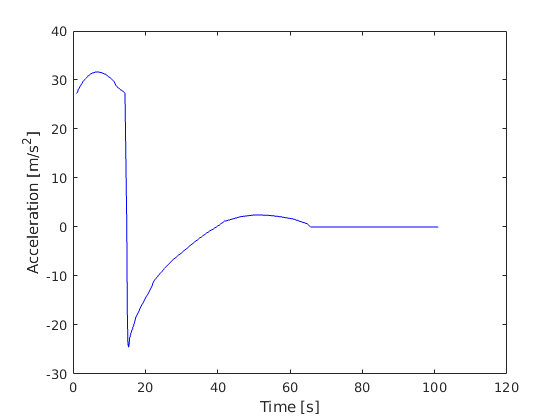

    if length (acc) > lt
        la=length(acc);
        acc(lt+1:la)=[];
    end
% plot results   
figure (1)
plot (T,acc,'b-')
ylabel ('Acceleration [m/s^2]')
xlabel ('Time [s]')

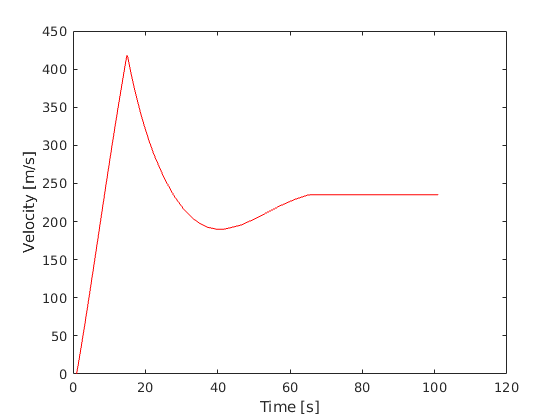

figure (2)
plot (T,Y(:,1),'r-')
ylabel ('Velocity [m/s]')
xlabel ('Time [s]')

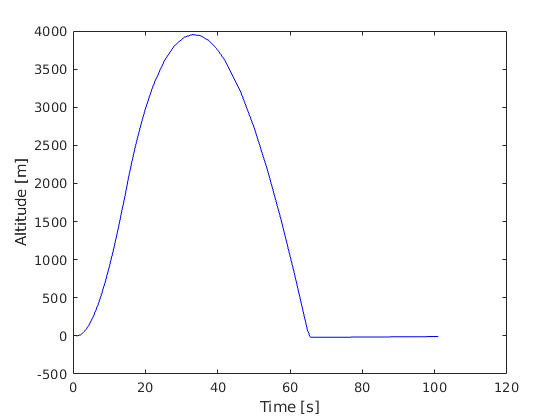

figure (3)
plot (T,Y(:,2)-r0,'b-')
ylabel ('Altitude [m]')
xlabel ('Time [s]')

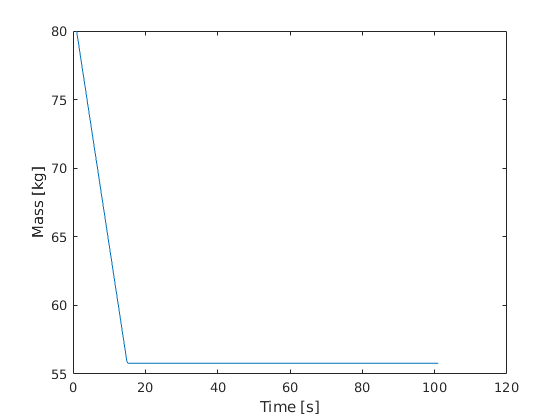

figure (4)
plot (T,Y(:,3))
ylabel ('Mass [kg]')
xlabel ('Time [s]')

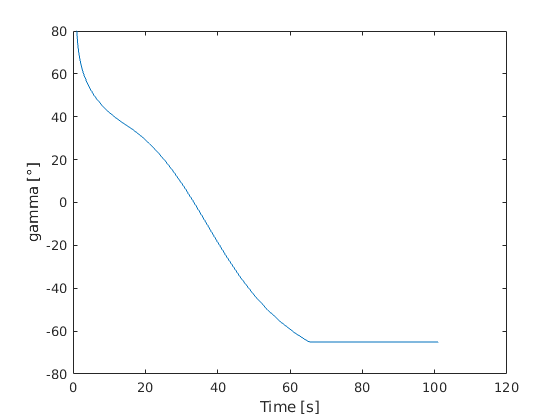

figure (5)
plot (T,Y(:,4)*180/pi)
ylabel ('gamma [°]')
xlabel ('Time [s]')